For CSTR Pulse

clc 
clear

% reactor properties
v=1;
V =220;
tau = V/v;

% for pulse
C_pulse = [1 2]; %an array of values
time_pulse = [1 2];% an array of corresponding time values

len = length(C_pulse);

% Resident Time Distribution
sum =0;
for i=1:len-1
    sum = sum + (time_pulse(i+1)-time_pulse(i))*(C_pulse(i+1)-C_pulse(i))/2;
end

E_exp = C_pulse/sum;

% Theroretical Calculations
E_theo = exp(-time_pulse/tau)/tau;

% for t_mean
sum_t = 0;
for i = 1:len-1
sum_t = sum_t + (time_pulse(i+1)+time_pulse(i))*(time_pulse(i+1)-time_pulse(i))*(C_pulse(i+1)+C_pulse(i))/4;
end

t_mean = sum_t/sum;

% Variance calulation tiem 

sum_v =0

sum_v = 0

for i = 1:len-1
sum_v = sum_v + ((time_pulse(i+1)+time_pulse(i))^2)*(time_pulse(i+1)-time_pulse(i))*(C_pulse(i+1)+C_pulse(i))/8;
end

variance = sum_v/sum - t_mean^(2)

variance = -13.5000

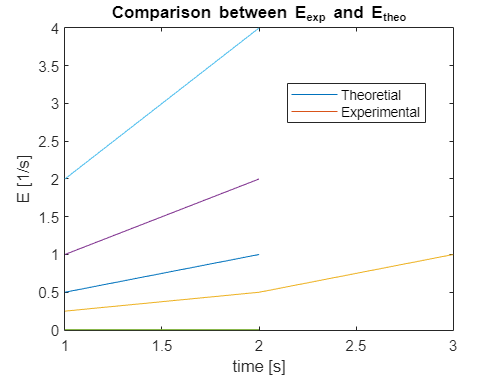



% Plotting Concentrations
plot(time_pulse,C_pulse)
xlabel("Time [s]")
ylabel("Concentration (conductivity) [micro siemens]")
title("Concentration vs Time for pulse input in CSTR")

% plotting E_exp and E_theo
plot(time_pulse, E_theo)
hold on
plot(time_pulse, E_exp)
legend('Theoretial', 'Experimental', 'Location', 'best')
xlabel("time [s]")
ylabel("E [1/s]")
title("Comparison between E_{exp} and E_{theo}")
hold off

For STEP input

C_both=[1 2 4]

C_both =      1     2     4


C_LFR=[3 5 9]

C_LFR =      3     5     9


time_step = [1 2 3] % the time corresponding to the values,

time_step =      1     2     3



len = length(time_step);
C_o = C_both(len)

C_o = 4

F_exp_L = C_LFR/C_o

F_exp_L =     0.7500    1.2500    2.2500


E_exp_L = zeros(1,len-1);
for i = 1:len-1
    E_exp_L(i) = (F_exp_L(i+1) - F_exp_L(i))/(time_step(i+1) - time_step(i));
end

% for F_theo of LFR
F_theo_L = zeros(1,len);
for i = 1:len
    if time_step(i) >= tau/2
        F_theo_L(i) = 1 - (tau*tau)/(4*time_step(i)*time_step(i));
    end
end

% For LFR + CSTR
F_exp_both = C_both/C_o

F_exp_both =     0.2500    0.5000    1.0000


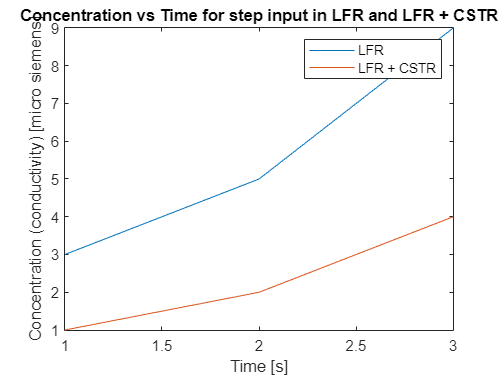

E_exp_both = zeros(1,len-1);
for i = 1:len-1
    E_exp_both(i) = (F_exp_both(i+1) - F_exp_both(i))/(time_step(i+1) - time_step(i));
end


% Plotting Concentrations
plot(time_step,C_LFR)
hold on
plot(time_step,C_both)
hold off
xlabel("Time [s]")
ylabel("Concentration (conductivity) [micro siemens]")
legend("LFR", "LFR + CSTR")
title("Concentration vs Time for step input in LFR and LFR + CSTR")

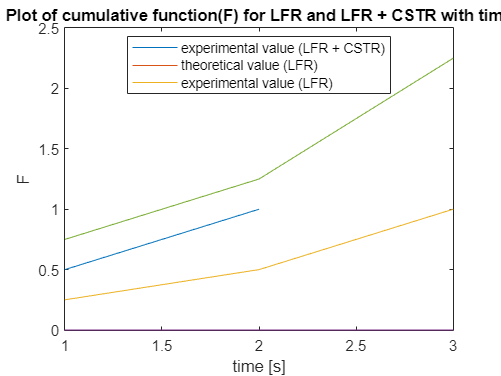


% Plotting E and F
plot(time_step(1:len-1),E_exp_L)
hold on
plot(time_step(1:len-1),E_exp_both)
legend('LFR', 'LFR + CSTR', 'Location', 'best')
xlabel("time [s]")
ylabel("E [1/s]")
title("Plot for E_{exp} vs time for LFR and LFR + CSTR")

% Plotting F theo and exp
plot(time_step, F_exp_both)
hold on
plot(time_step, F_theo_L)
plot(time_step, F_exp_L)
xlabel("time [s]")
ylabel("F")
legend('experimental value (LFR + CSTR)', 'theoretical value (LFR)', 'experimental value (LFR)','Location', 'best')
title("Plot of cumulative function(F) for LFR and LFR + CSTR with time")